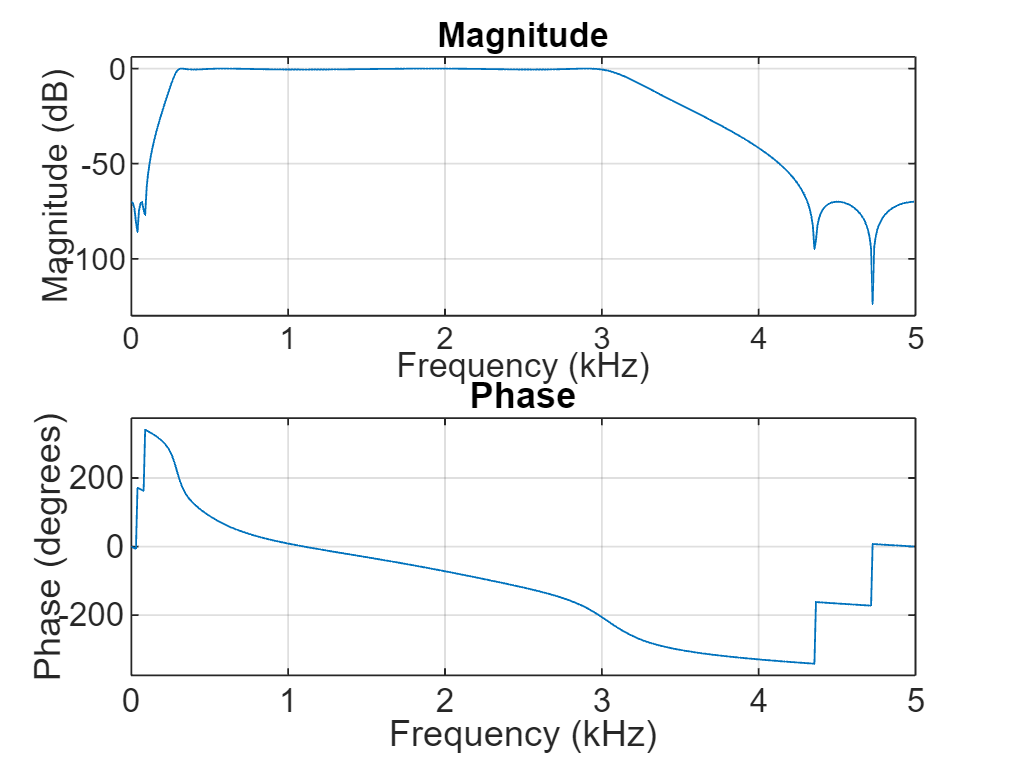

% fs = 1500;
% 
% [A,B,C,D] = ellip(10,3,40,[500 560]/(fs/2));
% sos = ss2sos(A,B,C,D);
% freqz(sos,[],fs)



cd 'E:\Rec Linda\Dup15\Batch1\DIV35_5337\20240625_Group_02\Well_8\Well_8_Mat_files'

x = load('Group02_Well8_012').data;
t_vec = 0:size(x,1)-1;






xfilt_h=Elliptic_filt(x,1);

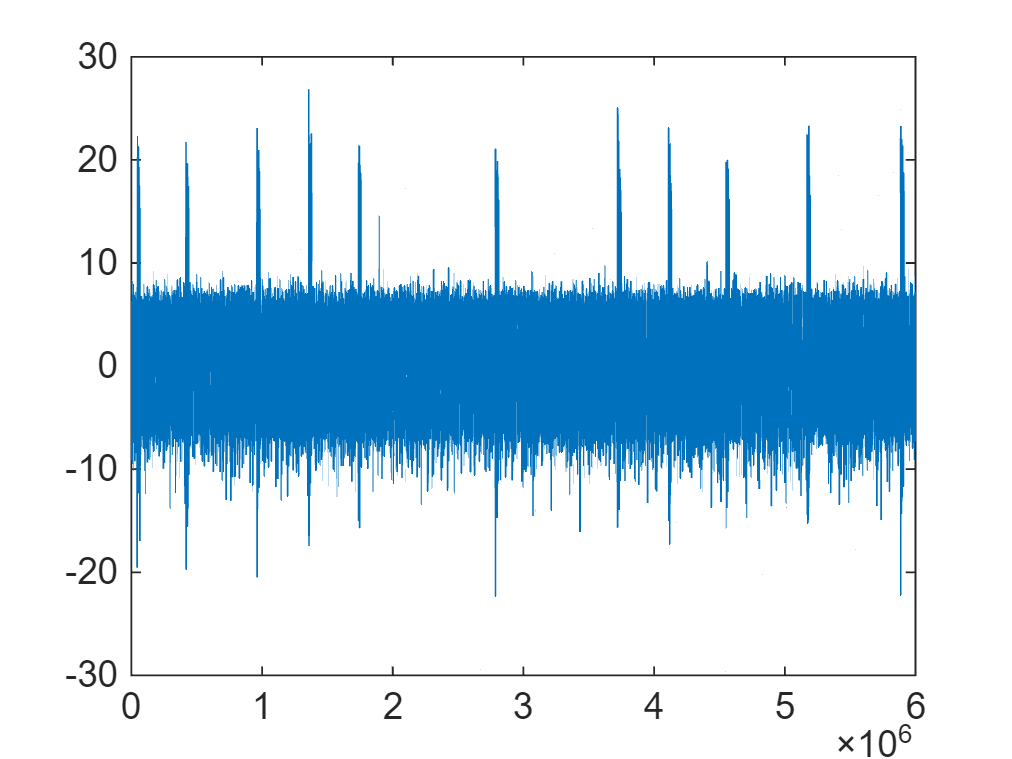


figure()
plot(t_vec,x);

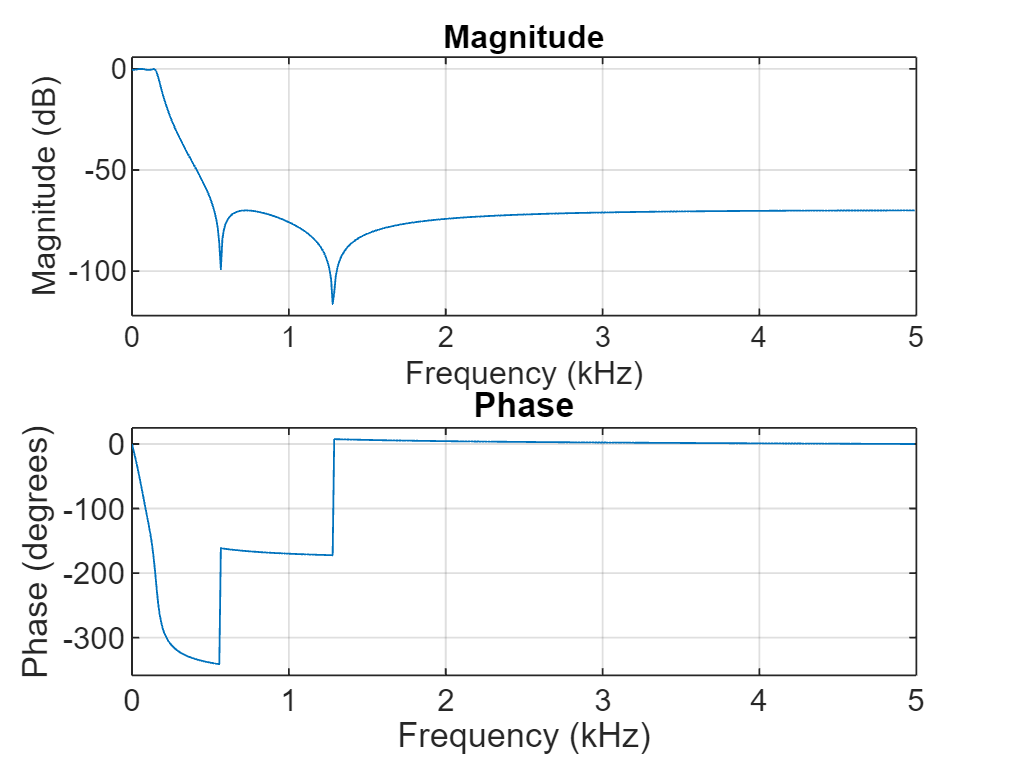

% hold on
% plot(t_vec,xfilt_h);
% hold off
% xlim([1345000 1365000])


xfilt_l=Elliptic_filt(x,2);

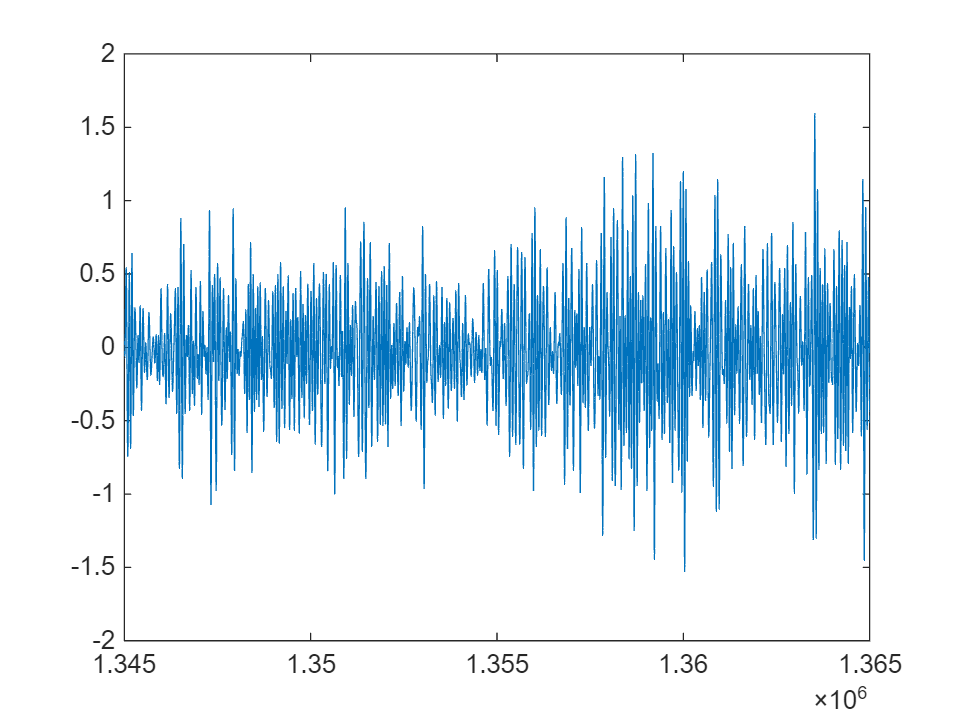

% 
% figure()
% % plot(t_vec,x);
% % hold on
% plot(t_vec,xfilt_l);
% 
% xlim([1345000 1365000])

% 
% % x_abs = abs(xfilt)
% % 
% % window_size = 10;
% % overlap = 5;
% % step_size = window_size - overlap

% % Define the sizes in ms terms
% 
% sigma = 2;         % Standard deviation (adjust as needed)
% kernel_size = 2*ceil(3*sigma) + 1; % Recommended kernel size (odd and ~6*sigma)
% center = (kernel_size - 1) / 2;
% m = -center:center;
% gaussian_kernel = exp(-(m.^2) / (2*sigma^2));
% 
% % Normalize the kernel so its elements sum to 1
% gaussian_kernel = gaussian_kernel / sum(gaussian_kernel);
% 
% 
% 
% disp('Gaussian Kernel:');
% disp(gaussian_kernel);
% 
% 

% % Gaussian smoothing window
% 
% fs = 10000;
% L = 2*fs; %ms
% w = gausswin(L);
% 
% % COnvolve with the absolute value of LFP traces 
% x_l_smooth = conv(abs(xfilt_l),w,'same')

x_l_smooth = 1.0e+03 *

    0.7375
    0.7377
    0.7378
    0.7380
    0.7381
    0.7382
    0.7384
    0.7385
    0.7387
    0.7388


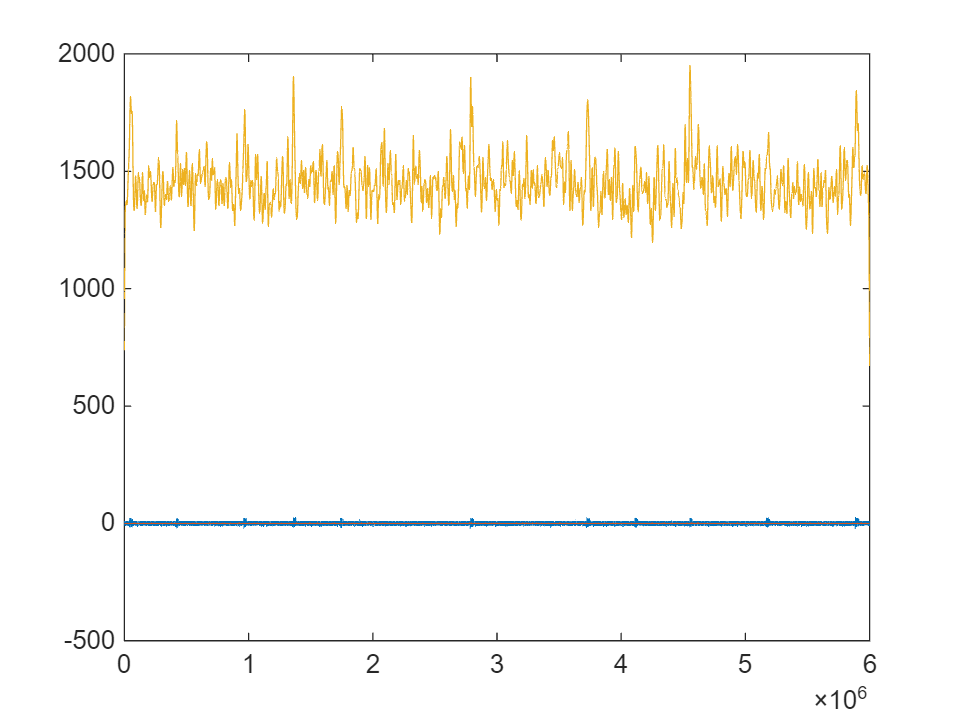

% 
% 
% plot(t_vec,x_l_smooth)



function x_filt = Elliptic_filt(x,Type)
 % 1 = 'bandpass' 2 = 'low'
%  Returns the filtered trace
    % Sampling frequency
    fs = 10000;
    
    % Filter order
    n = 4;
    %  Peak to peak passband ripple in dB
    Rp = 0.5;
    % Stopband attenuation in dB
    Rs = 70;

    if Type == 1
        % Passband edge frequency
        Wp = [300 3000];
        % Filter type
        fType = 'bandpass';
        
        
        [A,B,C,D] = ellip(n,Rp,Rs,Wp/(fs/2));
        sos = ss2sos(A,B,C,D);
        freqz(sos,[],fs);
    
        [b,a]  = ellip(n,Rp,Rs,Wp/(fs/2));
        x_filt = filtfilt(b,a,x);
    elseif Type == 2

        % Passband edge frequency
        Wp = 150;
        % Filter type
        fType = 'low';
        
        
        [A,B,C,D] = ellip(n,Rp,Rs,Wp/(fs/2));
        sos = ss2sos(A,B,C,D);
        freqz(sos,[],fs);
    
        [b,a]  = ellip(n,Rp,Rs,Wp/(fs/2));
        x_filt = filtfilt(b,a,x);
    end
end
    


